# Detector Evaluation

Load data and the trained YOLO network.

load ../data/PetsImages/petGroundTruth.mat
imds = imageDatastore(petGroundTruth.imageFilename)

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\Deep_Learning_with_MATLAB\data\PetsImages\Samoyed\Samoyed_175.jpg';
                              ' ...\Deep_Learning_with_MATLAB\data\PetsImages\Sphynx\Sphynx_201.jpg';
                              ' ...\Deep_Learning_with_MATLAB\data\PetsImages\Bengal\Bengal_135.jpg'
                               ... and 494 more
                              }
                     Folders: {
                              ' ...\MATLAB_Courses\Deep_Learning_with_MATLAB\data\PetsImages\Samoyed';
                              ' ...\MATLAB_Courses\Deep_Learning_with_MATLAB\data\PetsImages\Sphynx';
                              ' ...\MATLAB_Courses\Deep_Learning_with_MATLAB\data\PetsImages\Bengal'
                               ... and 2 more
                              }
    AlternateFileSystemRoots: {}

It takes several minutes to detect faces in all 497 images. You can run this code:

detector = trainNetwork();

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* Bengal
* Chihuahua
* Pug
* Samoyed
* Sphynx

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |         3.84 |         14.8 |          0.0010 |
|       4 |          50 |       00:00:29 |         0.62 |          0.4 |          0.0010 |
|       7 |         100 |       00:00:58 |         0.40 |          0.2 |          0.0010 |
|      10 |         150 |       00:01:26 |         0.22 |      4.9e-02 |          0.0010 |
|      14 |       

results = detect(detector, imds)

results = 497×3 table
          Boxes              Scores            Labels      
    __________________    ____________    _________________

    {[ 211 65 70 121]}    {[  0.8705]}    {[Samoyed      ]}
    {[ 145 5 184 199]}    {[  0.7927]}    {[Sphynx       ]}
    {[   16 18 58 62]}    {[  0.8178]}    {[Bengal       ]}
    {[109 47 251 191]}    {[  0.9036]}    {[Pug          ]}
    {0×4 double      }    {0×1 single}    {0×1 categorical}
    {[ 16 21 126 136]}    {[  0.9185]}    {[Chihuahua    ]}
    {[ 192 115 48 73]}    {[  0.7907]}    {[Samoyed      ]}
    {[  170 82 49 72]}    {[  0.8068]}    {[Samoyed      ]}
    {[236 62 105 116]}    {[  0.7784]}    {[Bengal       ]}
    {[  99 40 132 96]}    {[  0.8298]}    {[Pug          ]}
    {[   12 5 117 99]}    {[  0.9227]}    {[Chihuahua    ]}
    {[  95 1 247 220]}    {[  0.9065]}    {[Sphynx       ]}
    {[ 72 44 170 124]}    {[  0.925

Evaluate the precision for each class.

[averagePrecision, recall, precision] = evaluateDetectionPrecision(results, petGroundTruth(:, 2:end))

averagePrecision =     1.0000
    0.9800
    1.0000
    0.9899
    0.9700


recall = 5×1 cell array
    { 99×1 double}
    { 99×1 double}
    {101×1 double}
    { 99×1 double}
    { 98×1 double}


precision = 5×1 cell array
    { 99×1 double}
    { 99×1 double}
    {101×1 double}
    { 99×1 double}
    { 98×1 double}


Visualize the average precision per class.

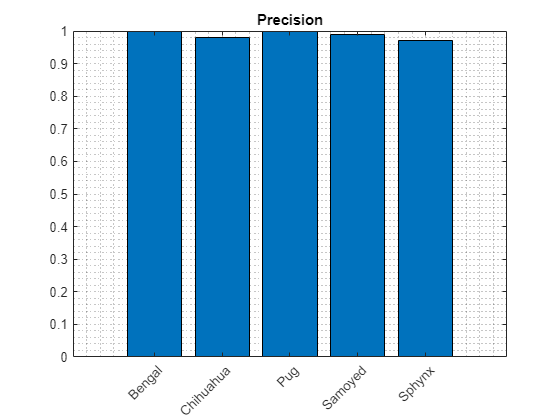

bar(averagePrecision)
grid minor
xticklabels(petGroundTruth.Properties.VariableNames(2:end))
xtickangle(45)
title("Precision")

The Precision-Recall curve is a popular visualization for object detectors. The curve is close to a 90 degree angle for all classes because the detector finds accurate bounding boxes for all classes. 

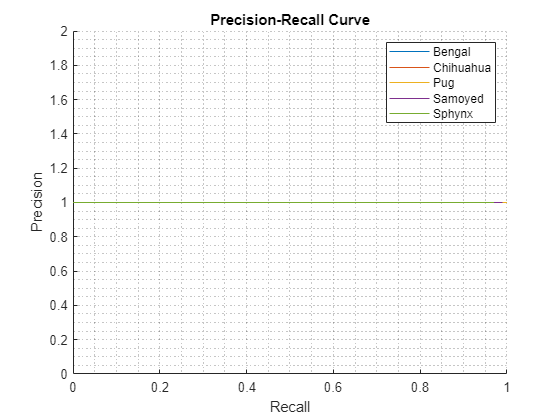

figure
hold on
for k = 1:numel(recall)
    plot(recall{k}, precision{k})
end
grid minor
hold off
xlabel("Recall")
ylabel("Precision")
title("Precision-Recall Curve")
legend(petGroundTruth.Properties.VariableNames(2:end))

Calculate the miss rates ("`detector`* didn"t find Pug in an image*") and false positive rates ("`detector`* thought Pug was in an image*"). 

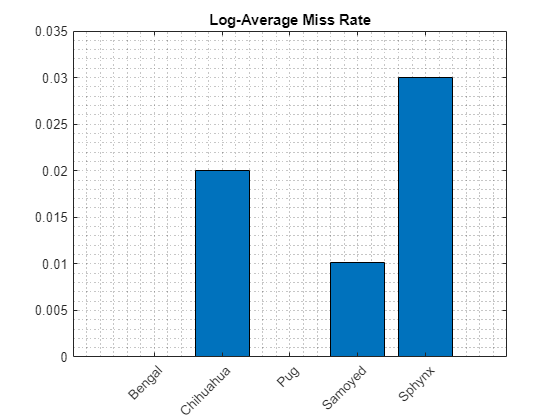

[am, fppi, missRate] = evaluateDetectionMissRate(results, petGroundTruth(:, 2:end));
bar(am)
grid minor
xticklabels(petGroundTruth.Properties.VariableNames(2:end))
xtickangle(45)
title("Log-Average Miss Rate")

function detector = trainNetwork()
    load ../data/PetsImages/petGroundTruth.mat petGroundTruth
    imds = imageDatastore(petGroundTruth.imageFilename);
    bxds = boxLabelDatastore(petGroundTruth(:, 2:end));
    data = combine(imds, bxds);
    scaledData = transform(data, @scaleGT);
    anchorBoxes = estimateAnchorBoxes(scaledData, 5);
    net = resnet18;
    numClasses = 5;
    imageSize = [224 224 3];
    lgraph = yolov2Layers(imageSize, numClasses, anchorBoxes, net,...
        "res5b_relu", "ReorgLayerSource", "res3a_relu");
    options = trainingOptions(  "adam", ...
                                "MiniBatchSize", 32, ...
                                "InitialLearnRate", 0.001, ...
                                "MaxEpochs", 15, ...
                                "Shuffle", "every-epoch", ...
                                "Verbose", true);
    detector = trainYOLOv2ObjectDetector(scaledData, lgraph, options);
end

function data = scaleGT(data)  
    targetSize = [224 224];
    % data{1} is the image
    scale = targetSize./size(data{1}, [1 2]);
    data{1} = imresize(data{1}, targetSize);
    % data{2} is the bounding box
    data{2} = bboxresize(data{2}, scale);
end